%first order response
s1 = load("lab4_order1_3.mat")

s1 = struct with fields:
    data: [330×1×1 iddata]
       t: [330×1 double]


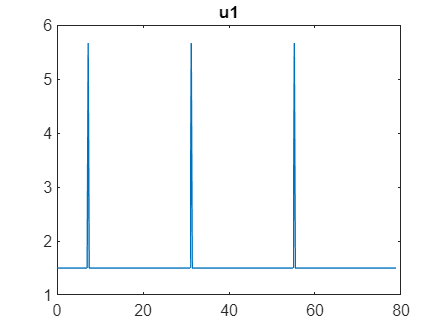


plot(s1.t,s1.data.InputData); title(s1.data.InputName);

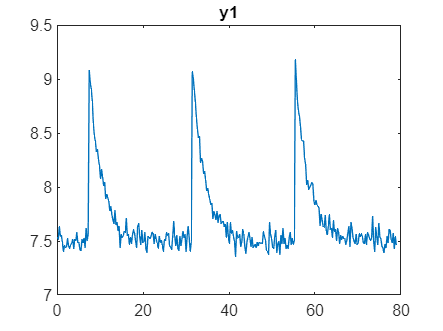

plot(s1.t,s1.data.OutputData); title(s1.data.OutputName);


uid = s1.data.InputData(1:110);
yid = s1.data.OutputData(1:110);
tid = s1.t(1:110);

uval = s1.data.InputData(111:330);
yval = s1.data.OutputData(111:330);
tval = s1.t(111:330);

y_ss = 1/11*sum(yid(100:110,:))

y_ss = 7.5072

u_ss = 1/11*sum(uid(100:110,:))

u_ss = 1.5000

y0 = 0;
u0 = 0;
t2 = 11.04;
t1 = 7.44;
T = t2-t1;

k = (y_ss-y0)/(u_ss-u0)

k = 5.0048

hs = tf(k,[T 1])

hs =
 
    5.005
  ---------
  3.6 s + 1
 
Continuous-time transfer function.




ymax = max(yid);
y0 = 7.53;
t = 0.368*(ymax-y0)+y0;

A = -1/T;
B = k/T;
C = 1;
D = 0;

Hss1 = ss(A,B,C,D)

Hss1 =
 
  A = 
            x1
   x1  -0.2778
 
  B = 
         u1
   x1  1.39
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




y_id_cap = lsim(Hss1,uid,tid,y_ss);
y_val_cap = lsim(Hss1,uval,tval,y_ss);

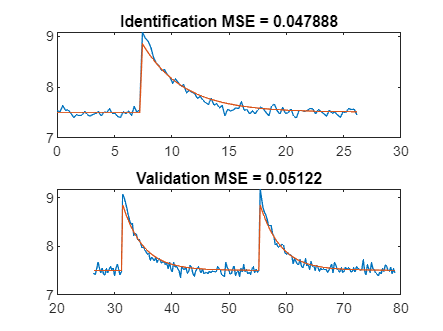


mse_id = mean(1/110*(yid)*sum((y_id_cap-yid).^2));
mse_val = mean(1/220*(yval)*sum((y_val_cap-yval).^2));

figure,
subplot(2,1,1);
plot(tid,yid,tid,y_id_cap); title("Identification MSE = " + string(mse_id))
subplot(2,1,2);
plot(tval,yval,tval,y_val_cap); title("Validation MSE = " + string(mse_val))

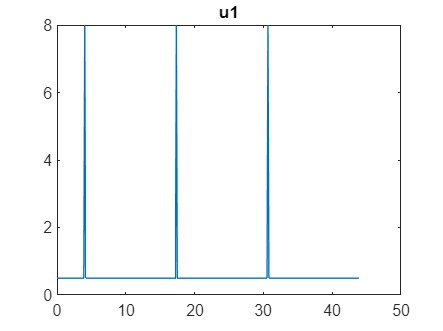


%second order impulse
s2 = load("lab4_order2_3.mat");

figure,
plot(s2.t,s2.data.InputData); title(s2.data.InputName);

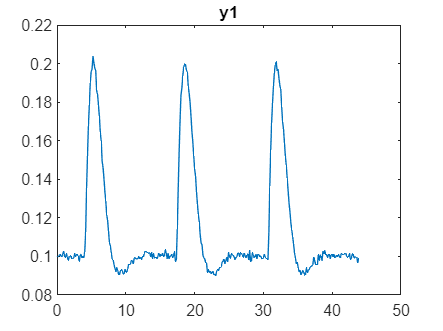

plot(s2.t,s2.data.OutputData); title(s2.data.OutputName);


id = struct("u",s2.data.InputData(1:110),"y",s2.data.OutputData(1:110),"t",s2.t(1:110));
val = struct("u",s2.data.InputData(111:330),"y",s2.data.OutputData(111:330),"t",s2.t(111:330));

y_ss = 1/11*sum(id.y(100:110,:))

y_ss = 0.1004

u_ss = 1/11*sum(id.u(100:110,:))

u_ss = 0.5000

t0 = 3.9;
t1 = 7.9;
t2 = 12.6;
t11 = 5.2;
t21 = 8.9;
T0 = 2*(t21-t11)

T0 = 7.4000

Ts = s2.t(2)-s2.t(1); % sampling time

k0 = t0/Ts;
k1 = t1/Ts;
k2 = t2/Ts;

ymax = max(yid);
y0 = 1/10*sum(yid(1:10,:))

y0 = 7.5025

t = 0.368*(ymax-y0)+y0;

k = y_ss/u_ss % gain

k = 0.2008


Aplus = Ts*sum(id.y(29:59)-y_ss);
Aminus = Ts*sum(y_ss-id.y(59:94));

M = Aminus/Aplus % overshoot

M = 0.0979

zeta = log(1/M)/(sqrt(pi^2+log(M)^2)) % damping factor

zeta = 0.5946

wn = 2/T0*sqrt(pi^2+(log(M)^2)) % natural frequency

wn = 1.0561

hs = tf(k*wn^2,[1 2*zeta*wn wn^2])

hs =
 
          0.224
  ---------------------
  s^2 + 1.256 s + 1.115
 
Continuous-time transfer function.




A = [0 1; -wn^2 -2*zeta*wn];
B = [0; k*wn^2];
C = [1 0];
D = 0;

Hss2 = ss(A,B,C,D)

Hss2 =
 
  A = 
           x1      x2
   x1       0       1
   x2  -1.115  -1.256
 
  B = 
          u1
   x1      0
   x2  0.224
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




y_id_cap = lsim(Hss2,id.u,id.t,[y_ss 0]);
y_val_cap = lsim(Hss2,val.u,val.t,[y_ss 0]);

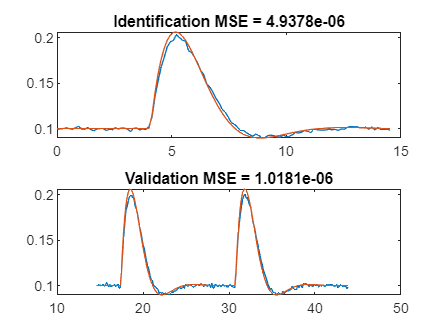


mse_id = mean(1/110*(id.u)*sum((y_id_cap-id.y).^2));
mse_val = mean(1/220*(val.y)*sum((y_val_cap-val.y).^2));

figure,
subplot(2,1,1);
plot(id.t,id.y,id.t,y_id_cap); title("Identification MSE = " + string(mse_id))
subplot(2,1,2);
plot(val.t,val.y,val.t,y_val_cap); title("Validation MSE = " + string(mse_val))